# Mean data for all nests

## create time binned and aligned data sets of all nests for the following parameters

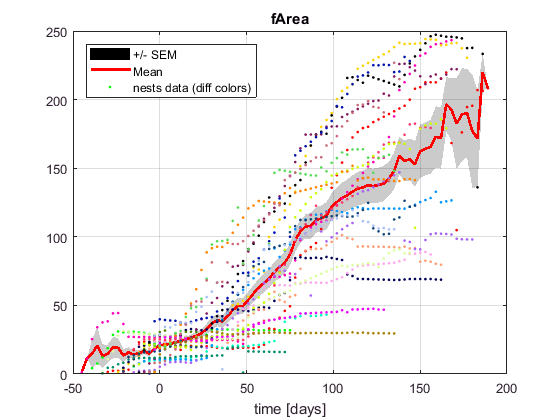

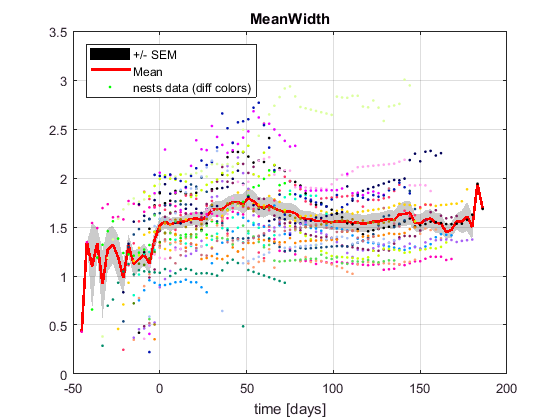

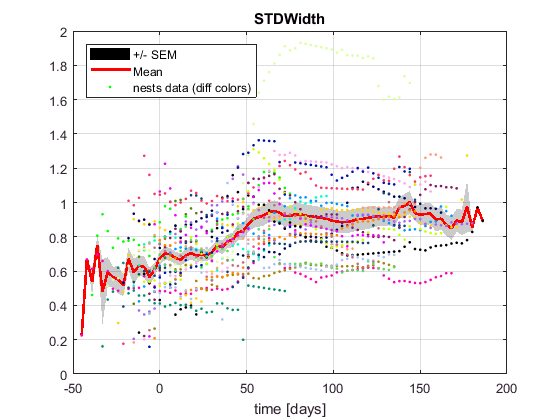

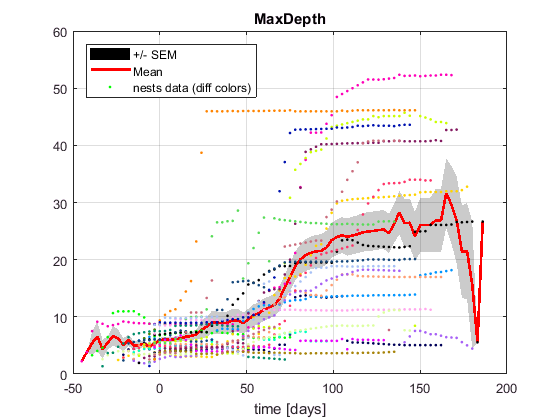

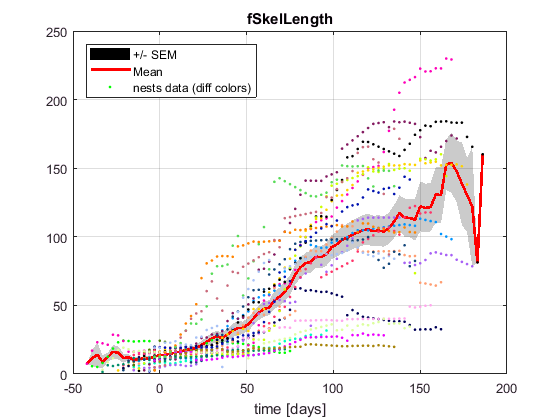

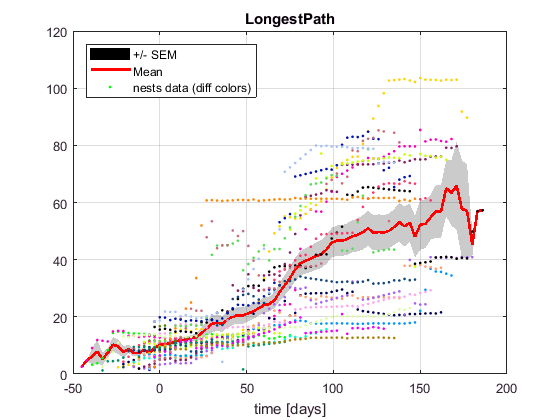

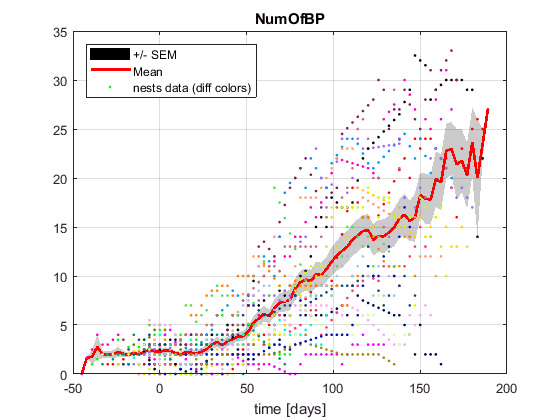

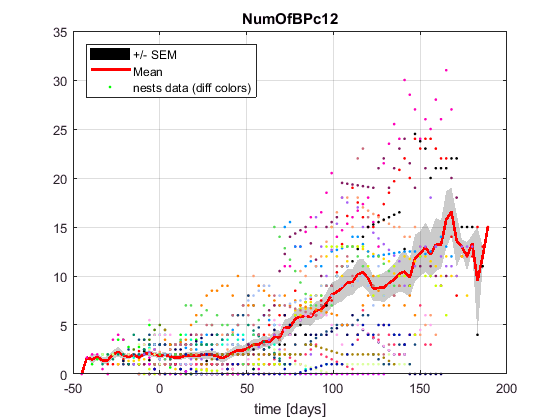

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')
UseNests = [2:8 10:13 15:18 20:29];
colors = distinguishable_colors(29,{'w',[0.5 0.5 0.5]});

for j=1:length(M)
    figure;
    er1 = M(j).Mean + M(j).SEM;
    er2 = M(j).Mean - M(j).SEM;
    idx = ~isnan(er1);
    f2 = fill([t(idx);flip(t(idx))],[er1(idx);flip(er2(idx))],'k','LineStyle','none');
    alpha(f2,0.2)
    hold on
    plot(t,M(j).Mean,'Color','r','LineWidth',2)
    for k=UseNests
        scatter(t,M(j).BinMat(:,k),[],colors(k,:),'.')
        hold on
    end
    %xlim([t2(1),t2(end)])
    %ylim([0 275])
    title(varNames{j})
    xlabel('time [days]')
    %ylabel('functional Area [cm^2]')
    legend('+/- SEM','Mean','nests data (diff colors)','Location','northwest')
    grid on
end

## **fArea plots**

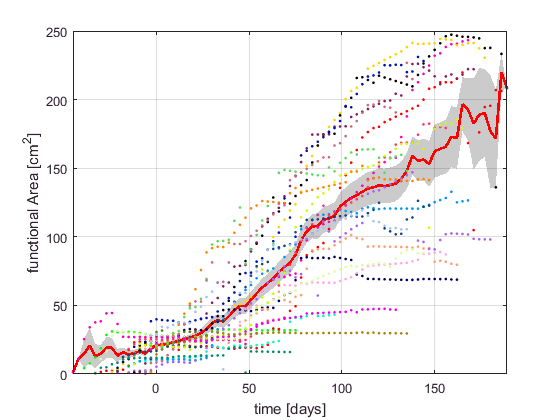

    figure;
    j=1;
    er1 = M(j).Mean + M(j).SEM;
    er2 = M(j).Mean - M(j).SEM;
    idx = ~isnan(er1);
    f2 = fill([t(idx);flip(t(idx))],[er1(idx);flip(er2(idx))],'k','LineStyle','none');
    alpha(f2,0.2)
    hold on
    plot(t,M(j).Mean,'Color','r','LineWidth',2)
    for k=UseNests
        scatter(t,M(j).BinMat(:,k),[],colors(k,:),'.')
        hold on
    end
    xlim([t(find(idx,1,'first')),t(find(idx,1,'last'))])
    %ylim([0 275])
    
    xlabel('time [days]')
    ylabel('functional Area [cm^2]')
    %legend('Mean','nests data (diff colors)','Location','northwest')
    grid on

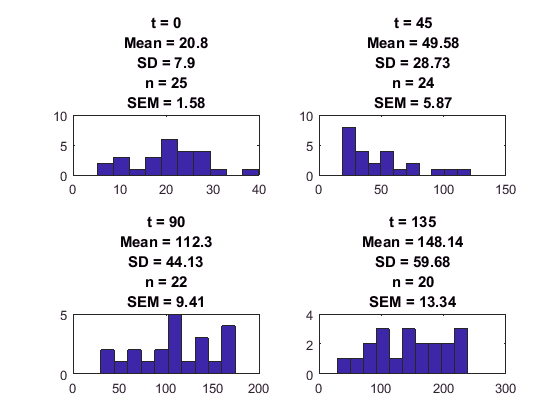

    figure
    for i=1:4
        subplot(2,2,i)
        hist(M(1).BinMat(t==(45.*(i-1)),:),10)
        title({['t = ',num2str(45.*(i-1))];...
            ['Mean = ',num2str(round(M(1).Mean(t==45.*(i-1)),2))];...
            ['SD = ',num2str(round(M(1).SD(t==45.*(i-1)),2))];...
            ['n = ',num2str(round(M(1).N(t==45.*(i-1)),2))];...
            ['SEM = ',num2str(round(M(1).SEM(t==45.*(i-1)),2))]})
    end

##     Stacked area plot of structure division

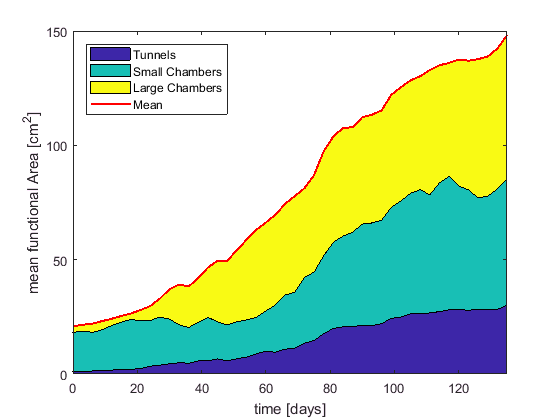

% fArea
figure
Y1  = [M(15).Mean M(18).Mean M(21).Mean];
area(t,Y1)
hold on
plot(t,M(1).Mean,'r','LineWidth',1.5)
xlim([0 135])
    xlabel('time [days]')
    ylabel('mean functional Area [cm^2]')
    legend('Tunnels','Small Chambers','Large Chambers','Mean','Location','northwest')

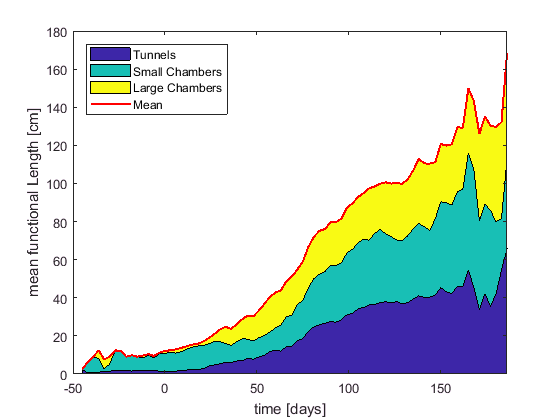

    
    
% fLength
figure
Y2  = [M(14).Mean M(17).Mean M(20).Mean];
SumY2 = sum(Y2,2);
area(t,Y2)
hold on
plot(t,SumY2,'r','LineWidth',1.5)
xlim([-50,186])
    xlabel('time [days]')
    ylabel('mean functional Length [cm]')
    legend('Tunnels','Small Chambers','Large Chambers','Mean','Location','northwest')

## Correlation between area and length (func)

figure
lm = fitlm(M(1).Mean,M(5).Mean)

lm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   ________    ________    ________    __________
    (Intercept)    -0.77725      1.2343    -0.62969       0.53081
    x1              0.74328    0.011321      65.654    5.0798e-68

Number of observations: 77, Error degrees of freedom: 75
Root Mean Squared Error: 6.17
R-squared: 0.983,  Adjusted R-Squared 0.983
F-statistic vs. constant model: 4.31e+03, p-value = 5.08e-68

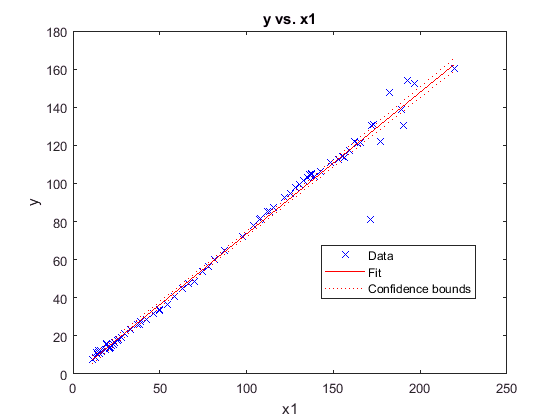

plot(lm)

## Pop vs. Area

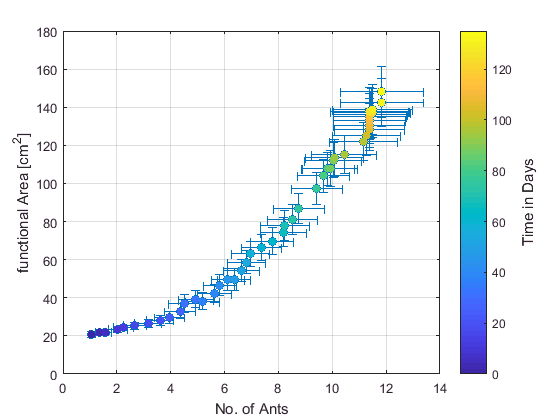

t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
A = M(1).Mean(t0:tend);
Aer = M(1).SEM(t0:tend);
N = M(13).Mean(t0:tend);
Ner = M(13).SEM(t0:tend);

figure
errorbar(N,A,Aer,Aer,Ner,Ner,'o')
hold on
scatter(N,A,[],t1,'filled')
xlabel('No. of Ants')
ylabel('functional Area [cm^2]')
grid on
c = colorbar;
c.Label.String = 'Time in Days'; c.Label.FontSize = 11;

%title('Mean fArea vs. Mean Population (error bars = SEM)- interpolated for missing values ')

## Check 3 structure classes vs. pop

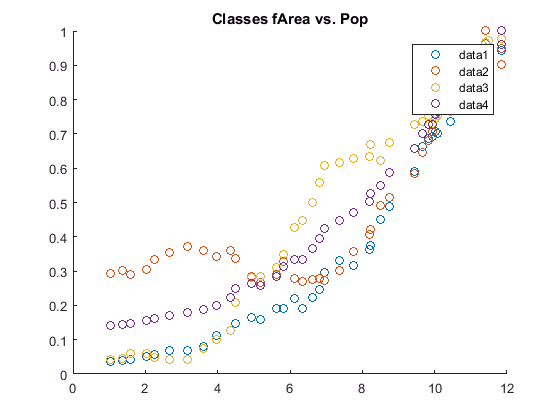

ans = 
  0×0 empty GraphicsPlaceholder array.


j = [15 18 21];
figure
for i=1:3
    hold on
    vec = M(j(i)).Mean(t0:tend);
    Max = max(vec);
    scatter(M(13).Mean(t0:tend),vec./Max)
    title('Classes fArea vs. Pop')
end
Max = max(M(1).Mean(t0:tend));
scatter(M(13).Mean(t0:tend),M(1).Mean(t0:tend)./Max)